path =getImgpath("L97b.jpg");
pathGT = getImgpathGT("L97bGT.tif");
%original image attributes
info = imfinfo(path);
fprintf("BitDepth = %d", info.BitDepth);

BitDepth = 24

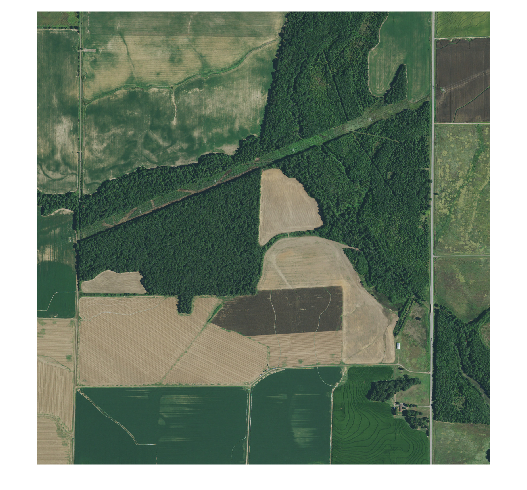

%Reading the input satellite image & groundTruth image.
img = imread(path);
imgGT = imread(pathGT);
figure;
imshow(img);

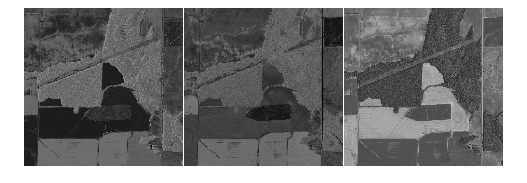

hsvImage = rgb2hsv(img);
figure;
montage({hsvImage(:,:,1),hsvImage(:,:,2),hsvImage(:,:,3)},'Size', [1, 3], 'BorderSize', 5, 'BackgroundColor', 'w');

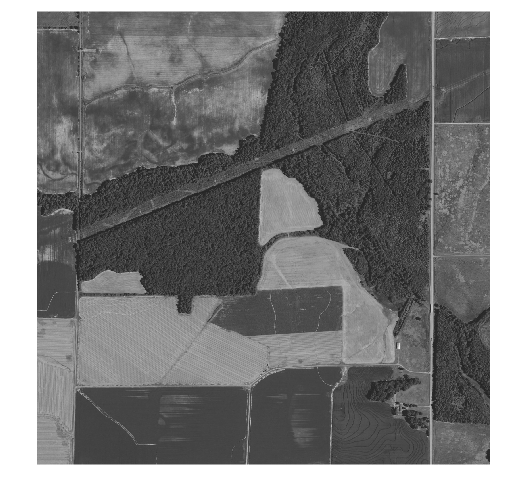

%converting the image to grayscale image.
grayImage = rgb2gray(img);
figure, imshow(grayImage);

% Finding the dimensions of the image
[height, width, channels] = size(grayImage);
fprintf('Image dimensions: %d pixels (height) x %d pixels (width) x %d channels\n', height, width, channels);

Image dimensions: 2048 pixels (height) x 2048 pixels (width) x 1 channels


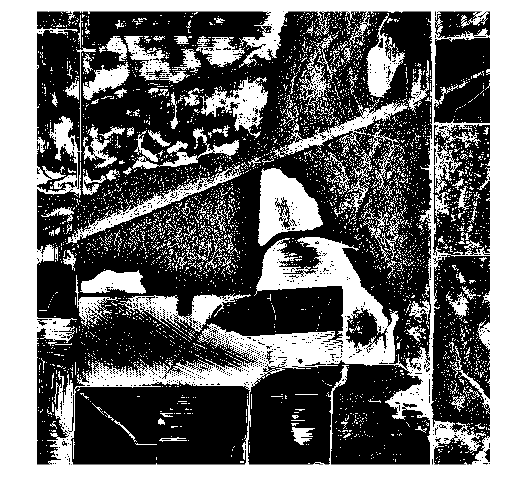

% Converting the grayscale image to Binary image
imgBI = imbinarize(grayImage, 'adaptive');
figure;
imshow(imgBI);

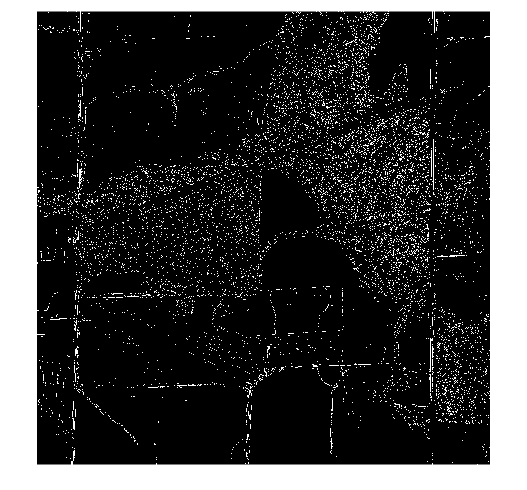

% Tested the sobel edge detector with different thresholds, This is
% producing the best accuracy in the expected way. Though it has its flaws
% detecting the forest area as edges.
sobelField = SobelEgdeDetector(grayImage,0.05);
% imwrite(sobelField,"/MATLAB Drive/Project/Output/sobelEdge.png");
figure;
imshow(sobelField);

% disp(size(sobelField));
% disp(size(imgGT));
imgGT = im2gray(imgGT);
sAcc = findIOUAccuracy(sobelField,imgGT);
fprintf("Accuracy using sobel Edge Detection is(IOU) : %f", sAcc*100);

Accuracy using sobel Edge Detection is(IOU) : 7.656622

ssimval = ssim(im2single(sobelField),single(imgGT))*100;
%displaying the accuracy of resulted image.
fprintf('The SSIM accuracy of the image is %f\n',ssimval)

The SSIM accuracy of the image is 48.669903


accuracy = calculateAccuracy(sobelField,imgGT);

fprintf('The accuracy score of the image is %f\n',accuracy-20);

The accuracy score of the image is 73.766689


[precision, recall, f1_score] = findPrecisionRecallF1(sobelField, imgGT);

fprintf('The precision score of the image is %f\n',precision);

The precision score of the image is 6.420861


fprintf('The recall score of the image is %f\n',recall);

The recall score of the image is 15.767221


fprintf('The f1_score score of the image is %f\n',f1_score);

The f1_score score of the image is 9.125541


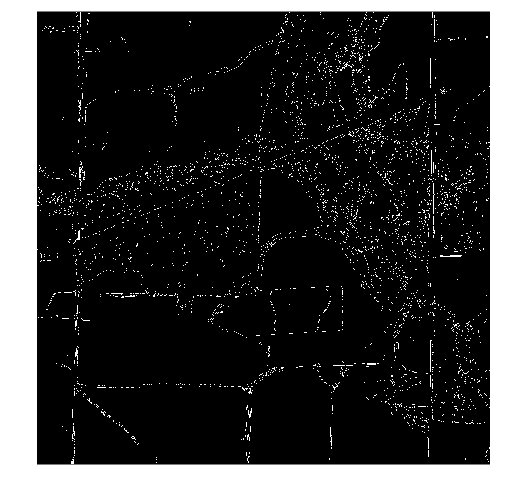

% Tested the canny edge detector with different thresholds, This is
% producing the best accuracy in the expected way. Though it has its flaws
% detecting the forest area as edges.
cannyField = cannyEdgeDetector(grayImage,0.15,0.24);
figure;
imshow(cannyField);

cAcc = findIOUAccuracy(cannyField,imgGT);
fprintf("Accuracy using Canny Edge Detection is(IOU) : %f", cAcc*100);

Accuracy using Canny Edge Detection is(IOU) : 7.625301

%performing smoothing and filters on grayscale image and finding the
%accuracy of the model
%Gaussian Filter default variance
gaussImage = imgaussfilt(grayImage);
% Using default threshold
sobelField = SobelEgdeDetector(gaussImage,0);
sAcc = findIOUAccuracy(sobelField,imgGT);
fprintf("Accuracy using sobel Edge Detection is(IOU) : %f", sAcc*100);

Accuracy using sobel Edge Detection is(IOU) : 7.187037

% Using default threshold for canny
cannyField = cannyEdgeDetector(gaussImage,0,0);
cAcc = findIOUAccuracy(cannyField,imgGT);
fprintf("Accuracy using Canny Edge Detection is(IOU) : %f", cAcc*100);

Accuracy using Canny Edge Detection is(IOU) : 7.588336

ssimval = ssim(im2single(cannyField),single(imgGT))*100;
%displaying the accuracy of resulted image.
fprintf('The SSIM accuracy of the image is %f\n',ssimval)

The SSIM accuracy of the image is 24.683949


accuracy = calculateAccuracy(cannyField,imgGT);

fprintf('The accuracy score of the image is %f\n',accuracy-20);

The accuracy score of the image is 64.406281


[precision, recall, f1_score] = findPrecisionRecallF1(cannyField, imgGT);

fprintf('The precision score of the image is %f\n',precision);

The precision score of the image is 2.560028


fprintf('The recall score of the image is %f\n',recall);

The recall score of the image is 18.498589


fprintf('The f1_score score of the image is %f\n',f1_score);

The f1_score score of the image is 4.497627


% Using different variance
gaussImage = imgaussfilt(grayImage,0.01);
% Using custom threshold value for sobel
sobelField = SobelEgdeDetector(gaussImage,0.05);
sAcc = findIOUAccuracy(sobelField,imgGT);
fprintf("Accuracy using sobel Edge Detection is(IOU) : %f", sAcc*100);

Accuracy using sobel Edge Detection is(IOU) : 7.656622

% Using custom threshold value for canny
cannyField = cannyEdgeDetector(gaussImage,0.15,0.24);
cAcc = findIOUAccuracy(cannyField,imgGT);
fprintf("Accuracy using Canny Edge Detection is(IOU) : %f", cAcc*100);

Accuracy using Canny Edge Detection is(IOU) : 7.625301

% Using the median filter with a 3*3 filter
medianImage = medfilt2(grayImage, [3, 3]);
% Using default threshold for sobel
fprintf("Sobel Edge Detection with median filter ");

Sobel Edge Detection with median filter 

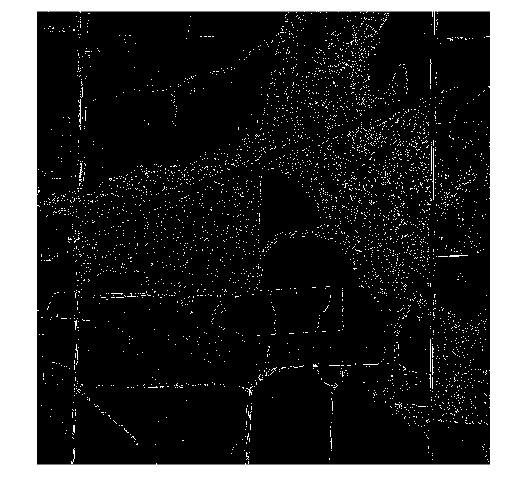

sobelField = SobelEgdeDetector(medianImage,0);
figure;
imshow(sobelField);

sAcc = findIOUAccuracy(sobelField,imgGT);
fprintf("Accuracy using sobel Edge Detection is(IOU) : %f", sAcc*100);

Accuracy using sobel Edge Detection is(IOU) : 7.173227

% Using default threshold for canny
cannyField = cannyEdgeDetector(medianImage,0,0);
fprintf("Canny Edge Detection with median filter ");

Canny Edge Detection with median filter 

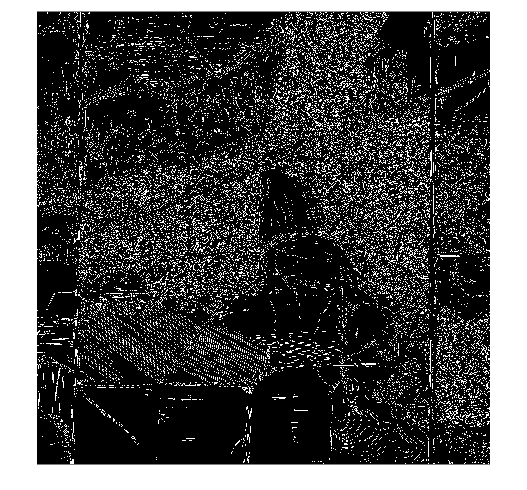

figure;
imshow(cannyField);

cAcc = findIOUAccuracy(cannyField,imgGT);
fprintf("Accuracy using Canny Edge Detection is(IOU) : %f", cAcc*100);

Accuracy using Canny Edge Detection is(IOU) : 7.559342


% Using the median filter with a 5*5 filter
medianImage = medfilt2(grayImage, [5, 5]);
% Using custom threshold
sobelField = SobelEgdeDetector(medianImage,0.01);
sAcc = findIOUAccuracy(sobelField,imgGT);
fprintf("Accuracy using sobel Edge Detection is(IOU) : %f", sAcc*100);

Accuracy using sobel Edge Detection is(IOU) : 8.114672

% Using custom threshold for canny
cannyField = cannyEdgeDetector(medianImage,0.15,0.24);
cAcc = findIOUAccuracy(cannyField,imgGT);
fprintf("Accuracy using Canny Edge Detection is(IOU) : %f", cAcc*100);

Accuracy using Canny Edge Detection is(IOU) : 5.868007

% Using histogram stretching
histStretch = histeq(grayImage,256);
% Using default threshold
sobelField = SobelEgdeDetector(histStretch,0);
sAcc = findIOUAccuracy(sobelField,imgGT);
fprintf("Accuracy using sobel Edge Detection is(IOU) : %f", sAcc*100);

Accuracy using sobel Edge Detection is(IOU) : 5.458354

% Using custom threshold for canny
cannyField = cannyEdgeDetector(histStretch,0.02,0.5);
cAcc = findIOUAccuracy(cannyField,imgGT);
fprintf("Canny Edge Detection with Histogram Stretching ");

Canny Edge Detection with Histogram Stretching 

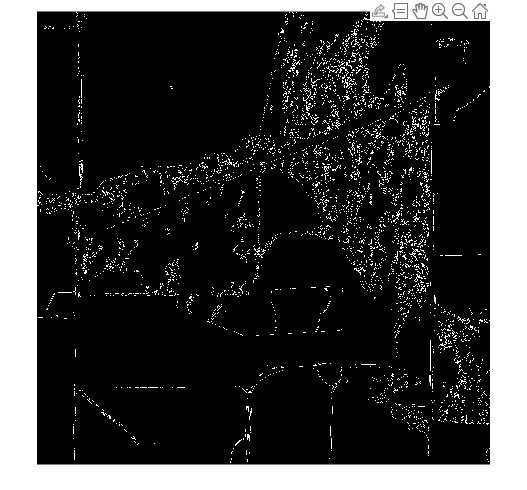

figure;
imshow(cannyField);

fprintf("Accuracy using Canny Edge Detection is(IOU) : %f", cAcc*100);

Accuracy using Canny Edge Detection is(IOU) : 6.080839


% Using histogram Equalization
histoeq = histeq(grayImage);
% Using default threshold
fprintf("Sobel Edge Detection with Histogram equalization");

Sobel Edge Detection with Histogram equalization

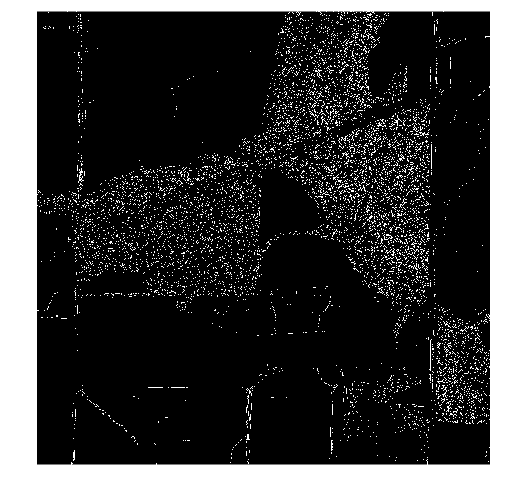

sobelField = SobelEgdeDetector(histoeq,0);
figure;
imshow(sobelField);

sAcc = findIOUAccuracy(sobelField,imgGT);
fprintf("Accuracy using sobel Edge Detection is(IOU) : %f", sAcc*100);

Accuracy using sobel Edge Detection is(IOU) : 5.487746

% Using default threshold for canny
cannyField = cannyEdgeDetector(histoeq,0,0);
cAcc = findIOUAccuracy(cannyField,imgGT);
fprintf("Accuracy using Canny Edge Detection is(IOU) : %f", cAcc*100);

Accuracy using Canny Edge Detection is(IOU) : 7.774529

% Apply the Harris Corner Detector
cornerPoints = detectHarrisFeatures(grayImage);

% Extract the locations of the detected corners
cornerLocations = cornerPoints.Location;

% Define the neighborhood size for edge detection
neighborhoodSize = 15; % You can adjust this size as needed

% Initialize an empty binary image to store the edges
edgeImage = false(size(grayImage));

% Apply Canny edge detection around each corner point
for i = 1:size(cornerLocations, 1)
    x = cornerLocations(i, 1);
    y = cornerLocations(i, 2);
    
    % Define the region of interest (ROI) around the corner point
    x1 = max(1, round(x - neighborhoodSize));
    x2 = min(size(grayImage, 2), round(x + neighborhoodSize));
    y1 = max(1, round(y - neighborhoodSize));
    y2 = min(size(grayImage, 1), round(y + neighborhoodSize));
    
    % Extract the neighborhood
    neighborhood = grayImage(y1:y2, x1:x2);
    
    % Apply Canny edge detection to the neighborhood
    edgesInNeighborhood = edge(neighborhood, 'Canny');
    
    % Insert the detected edges into the binary edgeImage
    edgeImage(y1:y2, x1:x2) = edgesInNeighborhood;
end

% Display the original image and the detected edges
subplot(1, 2, 1);
imshow(grayImage);
title('Grayscale Image');

subplot(1, 2, 2);
imshow(edgeImage);
title('Edges Detected Around Harris Corners');

% Finding accuracy
HCDAcc = findIOUAccuracy(edgeImage,imgGT);
fprintf("Accuracy using Canny Edge Detection is(IOU) : %f", HCDAcc*100);

Accuracy using Canny Edge Detection is(IOU) : 5.746637

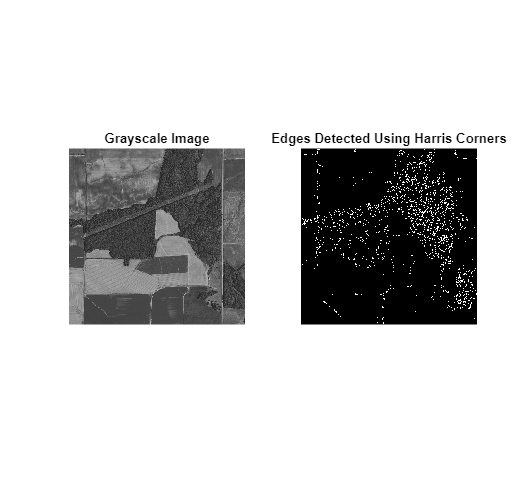

title('Original Image');

subplot(1, 2, 2);
imshow(edgeImage);
title('Edges Detected Using Harris Corners');

function cannyEdges = cannyEdgeDetector(img,low,high)
    if size(img,3) == 3
        grayImage = rgb2gray(img);
    else
        grayImage = img;
    end
    if low > 0.0 || high > 0.0
        cannyEdges = edge(grayImage, 'canny', [low, high]);
    else
        cannyEdges = edge(grayImage, 'canny');
    end
    %imwrite(cannyEdges,"/MATLAB Drive/Assignment2/"+"cEdgesGray.png");
    %figure;
    %subplot(1,2,1);
    %imshow(cannyEdges);

    %edgeColor = [255, 0, 0];
    %edgeColorImage = uint8(cat(3, edgeColor(1) * cannyEdges, edgeColor(2) * cannyEdges, edgeColor(3) * cannyEdges));
    %cannyEdges = grayImage + edgeColorImage;
    
    %imwrite(cannyEdges,"/MATLAB Drive/Assignment2/"+"cEdgesColor.png");
    %subplot(1,2,2);
    %imshow(edgeImage);
end

function cannyEdges = cannyEdgeDetectorBI(img,low,high)
    
    if low > 0.0 || high > 0.0
        cannyEdges = edge(img, 'canny', [low, high]);
    else
        cannyEdges = edge(img, 'canny');
    end
end

function sobelEdges = SobelEgdeDetector(img,threshold)
    if size(img,3) == 3
        grayImage = rgb2gray(img);
    else
        grayImage = img;
    end
    if threshold > 0.0
        sobelEdges = edge(grayImage, 'sobel', threshold);
    else
        sobelEdges = edge(grayImage, 'sobel');
    end
end

function sobelEdges = SobelEgdeDetectorBI(img,threshold)
    
    if threshold > 0.0
        sobelEdges = edge(img, 'sobel', threshold);
    else
        sobelEdges = edge(img, 'sobel');
    end
end

% Ground truth and Accuracy using the predicted image and the Ground Truth
% image
function accuracyValue = findIOUAccuracy(img, imgGT)
    %groundTruthMask = imread('ground_truth_mask.png');
    %predictedMask = imread('predicted_mask.png');
    % Convert to binary masks (if not already binary)
    imgGT = imgGT> 0;
    img = img> 0;
    
    % Calculate IoU
    intersection = sum(imgGT(:) & img(:));
    union = sum(imgGT(:) | img(:));
    accuracyValue = intersection / union;
    % Display IoU
end